A = imread("2019116007.jpg");
a = rgb2gray(A);
[r,c] = size(a);

%fourier transform
dft = fft2(a);
%centred spectrum
shifted = fftshift(dft);
centred = abs(shifted);

%original image
subplot(441);
imshow(a);title("original image");

%fourier transform
subplot(446);
imagesc(abs(dft));title("Fourier Spectrum");

%centred spectrum
subplot(447)
imagesc(centred);title("Centred Spectrum");

%reconstruction
b1 = ifft2(dft);
subplot(4,4,13);
imshow(b1,[]);title("Reconstructed using IFT");
subplot(442);
b = fftshift(b1);
imshow(b,[]);title("Shifted img");
subplot(445);
imshow(log(b1),[]);title("Log of absoulte inverse");

%frequency component
freq = shifted;
freq(1:50,50:100) = 0;
subplot(443);
imshow(abs(ifft2(freq)),[]);title("Certain freq removed");

%cosine transform
c = dct2(a);
disp("DCT Coefficients=");

DCT Coefficients=


disp(c(1:20,1:20));

   1.0e+04 *

    8.5157    0.1184    1.5102   -0.0807   -0.1923   -0.0894   -0.3493    0.1054    0.1701   -0.0194    0.1341   -0.0692   -0.0278   -0.0250   -0.0813    0.0630    0.0819   -0.0130    0.0373   -0.0250
    0.9548    0.0477    1.1582   -0.1177   -0.1321   -0.0570   -0.2701    0.1804   -0.0271   -0.0048    0.1655   -0.0535   -0.0354    0.0108   -0.1714    0.0642    0.0419   -0.0076    0.0820   -0.0582
   -0.8670    0.0856   -0.2452   -0.0877   -0.0519   -0.0287    0.0548    0.0601   -0.0858   -0.0591    0.0691   -0.0228    0.0285    0.0112   -0.0203   -0.0245    0.0287    0.0181   -0.0078    0.0247
    0.1144    0.0298    0.0160   -0.0765    0.0542    0.0620    0.1235    0.0193    0.0440   -0.0114   -0.1528    0.0230   -0.0232    0.0309    0.1850   -0.0299   -0.1117   -0.0159   -0.0870    0.0233
    0.6585    0.0357   -0.1870   -0.0618   -0.3586    0.0582    0.3327   -0.0417   -0.0041   -0.0617   -0.1612    0.0457    0.0261    0.0100    0.1518   -0.0589   -0.0708    0.0191  

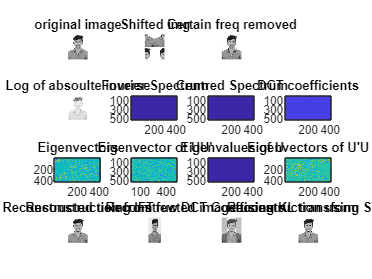

%reconstruction from fewer coefficients
d = idct2(c(1:200,1:100));
subplot(448);
imagesc(c);title("DCT coefficients");
subplot(4,4,14);
imshow(d,[]);title("Reconstruction from few DCT Coefficients");

%KL transform
img = im2double(a);
m = mean(img);
v = img-m;
C = cov(img);
[evec,eval] = eig(C);
eigen_values = diag(eval);
[Descend_eval,indices] = sort(eigen_values,"descend");
eigen_vectors = evec(:,indices);
reconstructed = (v*eigen_vectors)*eigen_vectors';
subplot(449);
imagesc(evec);title("Eigenvectors");
subplot(4,4,15);
imshow(reconstructed,[]);title("Reconstructed image using KL transform");

%SVD 
[U,S,V] = svd(img);
transimg = U*S*V';
subplot(4,4,10);
imagesc(U);title("Eigenvector of UU'");
subplot(4,4,11);
imagesc(S);title("Eigenvalues of U");
subplot(4,4,12);
imagesc(V);title("Eigenvectors of U'U");
subplot(4,4,16);
imshow(transimg);title("Reconstruction using SVD");